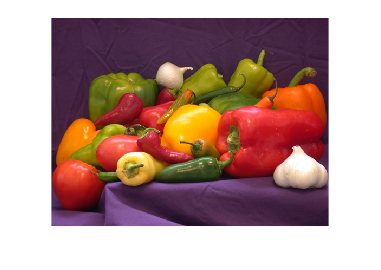

clear
f=imread('peppers.png');
f1=double(f);
for i=1:3
    g(:,:,i)=dct2(f1(:,:,i));  %对rgb各分量分别做快速傅里叶变换方法的dct变换
end
g(abs(g)<0.1)=0;  %dct系数小于0.1的变成0实现压缩
for i=1:3
    f2(:,:,i)=idct2(g(:,:,i));  %逆dct变换
end
f2=uint8(f2);
imshow(f)

imshow(f2)